Characteristics of the low pass multiple feedback Butterworth filter

G = tf([-3787878787.8788],[1,123106.06,3787878787.87788])

G =
 
           -3.788e09
  ---------------------------
  s^2 + 1.231e05 s + 3.788e09
 
Continuous-time transfer function.
Model Properties


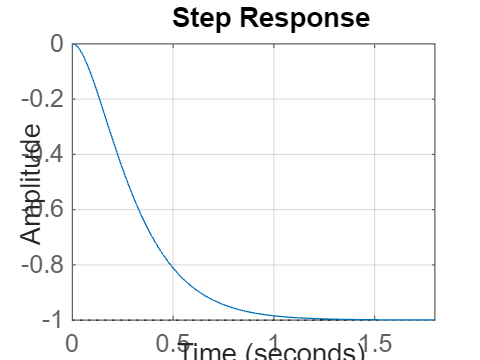


figure()
step(G)
grid on

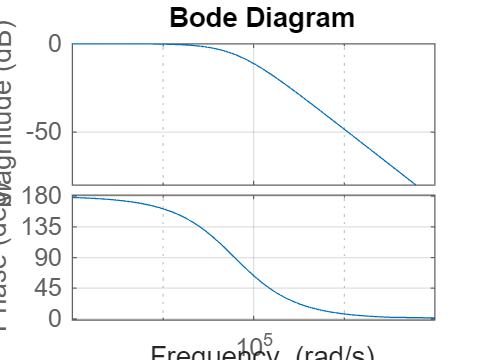


figure()
bode(G)
grid on

FFT of quantized and holded sine

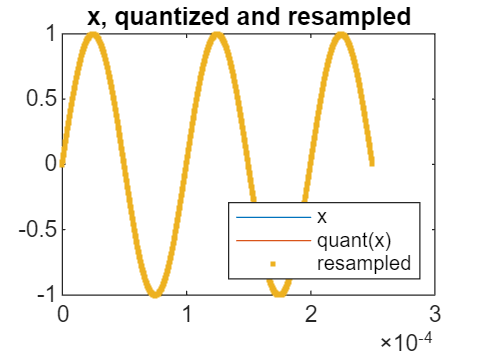

q_step = 16;

f = 10000;
periods = 2.5;
Tm = periods/f;
fs = f*1000;
Ts = 1/fs;
N = Tm*fs;

ups = 1000;
fs_d = ups*fs;
Ts_d = 1/fs_d;

t = 0:Ts:Tm-Ts;
tu = [0:Ts_d:Tm-Ts_d];
x = sin(2*pi*f*t);
x_q = quantizenumeric(x,1,1+q_step,q_step);
q = resample(x_q,ups,1,0);
dl = floor(ups/2);

figure()
plot(t,x)
hold on
stairs(t,x_q)
plot(tu(1+dl:end),q(1:end-dl),'.')
hold off
title('x, quantized and resampled')
legend('x','quant(x)','resampled','Location','southeast')

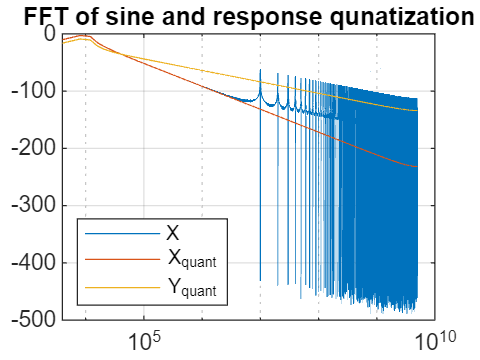


% FFT for non coherent sampling
N_ups = N*ups;
x_ups = sin(2*pi*f*tu);
X_q = abs(fft(q))/N_ups;
X_ups = abs(fft(x_ups))/N_ups;

fu = [0:1/Tm:fs_d-1/Tm];
fu_egyold = fu(1:floor(end/2));

X_ups_egyold = X_ups(1:floor(end/2));
X_ups_egyold(2:end) = 2*X_ups_egyold(2:end);
X_q_egyold = X_q(1:floor(end/2));
X_q_egyold(2:end) = 2*X_q_egyold(2:end);

y_q = lsim(G,q,tu);
Y_q = abs(fft(y_q))/N_ups;
Y_q_egyold = Y_q(1:floor(end/2));
Y_q_egyold(2:end) = 2*Y_q_egyold(2:end);

figure()
semilogx(fu_egyold,20*log10(X_q_egyold));
hold on
semilogx(fu_egyold,20*log10(X_ups_egyold))
semilogx(fu_egyold,20*log10(Y_q_egyold))
hold off
grid on;
title('FFT of sine and response qunatization')
legend('X','X_{quant}','Y_{quant}','Location','southwest')